# **Descrierea formelor**

## **Notiuni generale**

- **scop: **odată **identificate** **regiunile**, încercăm să le **diferențiem** de celelalte prin **determinarea** unor **caracteristici** **speciale**

###     a. Etichetarea

- similara cu **segmentarea cu praguri multiple**, prin care se pot crea diferite regiuni pe baza intervalelor de selecție de prag, coloate diferit

- 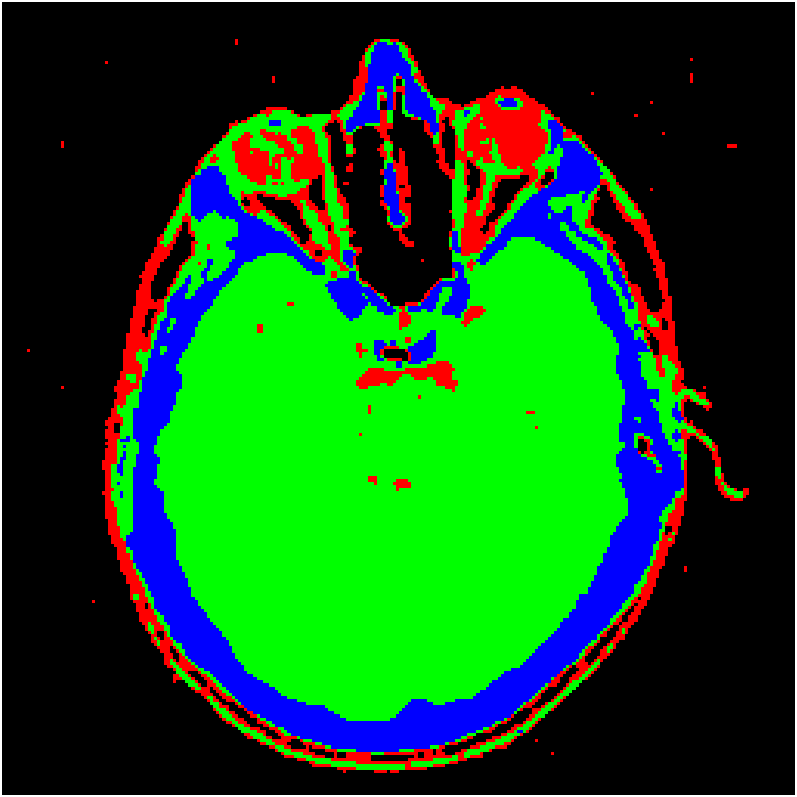

###     b. Descriptori de regiuni

- Pe langa colorare putem **descrie o regiune** și prin intermediul unor **scalari simpli euristici**

#### **        Aria **

**            - Numarul de pixeli **dintr-o regiune

#### **        Primetrul**

**            - Lungimea frontierei**, determinată ca **numărul** de **pixeli** aparținând **frontierei închise a regiunii**

#### **        Compactitatea **

**            - Raportul dintre patratul perimetrului si arie**

### **c**. Matlab functions

####     **etichetarea regiunilor **==> **bwlabel(bw, n)**

- **n - tipul conectarii frontierei (cu 4 sau cu 8 pixeli)**

- **daca dorim sa returnam si numarul de obiecte/regiuni din imagine, punem un al doilea parametru la return**

original = imread('circlesBrightDark.png');
[l, nrRegions] = bwlabel(~imbinarize(original), 8);
nrRegions
figure();
imshow(original);
hold on;
[r, c] = find(l == 3);
plot(c, r, 'o');  title('Label of region i');

####     descrierea** regiunilor imaginii **==> regionprops**(bw, properties)**

- **Properties:**

- **    'Area', 'BoundingBox', 'Centroid', 'Perimeter',...**

original = imread('text.png');
l = regionprops(original, 'BoundingBox');
figure();
imshow(original);
hold on
for i = 1:length(l)
    rectangle('Position',l(i).BoundingBox,'EdgeColor','red');  
end
title('BoundingBox of all the detected elements');

#### operații morfologice ==> bwmorph**(bw, operation, n)**

- **Operation:**

- **    'clean', 'close', 'fill', 'open',...**

- **operația poate fi aplicată de n ori**

original = imread('circles.png');
l = bwmorph(original, 'remove');
l = bwmorph(l, 'thicken', 3);
figure();
imshowpair(original, l, 'montage');

#### obținerea perimetrului dintr-o imagine binară ==> bwperim**(bw, connection)**

- **connection: 4, 8 (2D) 6, 18, 26 (3D)**

original = imread('cameraman.tif');
l = bwperim(imbinarize(original));
figure();
imshowpair(original, l, 'montage');

#### selectarea regiunilor ==> bwselect**(bw, n)**

- **n - tipul conectarii frontierei (cu 4 sau cu 8 pixeli)**

original = imread('coins.png');
l = bwselect(im2bw(original), 8);
figure();
imshowpair(original, l, 'montage');

## Exemplul

% Pas 1: Citirea si afisarea imaginii
I = imread('rice.png');
figure, imshow(I);
pause

% Pas 2: Estimarea valorii aproximative a pixelilor din fundal
% Se foloseste open (deschiderea imaginii) pentru eliminarea obiectelor din
% imagine
se = strel('disk',15);
background = imopen(I,se);
figure, imshow(background);
pause

% Pas 3: Vizualizarea fundalului ca o suprafata
% Se foloseste functia surf - vezi help
figure, surf( double(background(1:8:end,1:8:end)) ) ,zlim([0 255]);
set(gca,'ydir','reverse');
pause

% Pas 4: Crearea unei imagini cu fundal uniform
% Se foloseste diferenta imaginilor : functia imsubstract
I2 = imsubtract(I,background);
figure, imshow(I2);
pause

% Pas 5: Ajustarea contrastului imaginii
% Se mareste contrastul folosind imadjust (vezi lucrari de laborator precedente)
I3 = imadjust(I2, stretchlim(I2), []);
%I3 = histeq(I2);
figure, imshow(I3);
pause

% Pas 6: Binarizarea imaginii
level = graythresh(I3);
bw = im2bw(I3,level);
figure, imshow(bw);
pause;

% Pas 7: Determinarea numărului de obiecte din imagine şi etichetarea regiunilor
% Se foloseste bwlabel – vezi help
[labeled,numObjects] = bwlabel(bw,4);
numObjects
pause

% Pas 8: Examinarea matricii etichetate
% Vizualizaţi portiuni din imagine folosind imcrop
figure, imshow(labeled);
pause

% Pas 9: Vizualizarea imaginii etichetate ca o imagine color indexată
% Colorarea imaginii folosind o paletă de culori (similar colorarii din referatele
% precedente)
pseudo_color = label2rgb(labeled, @spring, 'c', 'shuffle');
figure, imshow(pseudo_color);
pause

% Pas 10: Masurarea diferitelor proprietati ale obiectelor din imagine
% Functia regionprops calculează proprietătile enumerate ale regiunilor din imaginea etichetata – vezi help
graindata = regionprops(labeled,'basic')
pause

% Afisarea suprafetei regiunii 51
graindata(51).Area
pause

% Afisarea dreptunghiului de dimensiuni minime ce poate conţine regiunea
% Afisarea centrului de masa a regiunii 51
graindata(51).BoundingBox, graindata(51).Centroid
pause

% Pas 11: Calcul statistic al obiectelor din imagine
% Aria maxima a unui obiect din imagine
max([graindata.Area])
pause

% Gasirea indicelui obiectului de arie 404
biggrain = find([graindata.Area]==404)
pause

% Calcularea ariei medii
mean([graindata.Area])
pause

% Calcularea unei histograme alcătuite din 20 de obiecte care arata distribuţia
% ariilor
figure, hist([graindata.Area],20)
pause
